# Echo Phase Graph for Prostate Tissue

Luminal Water Imaging is showing promise at differentiating prostate tissues baed on differing T2s. Question is if we can improve this through sequence or fitting modifications. In particlar to remove the 'shaky' T2 fitting and the lack of diffusion or perfusion information.

First plot a basic CPMG sequence for two compartments using a standard exponential decay. Noise adds an offset which looks a bit like the long T2 component. More noise is like "more" longT2 and a "higher" lwf. We can add noise using `addimnoise` 

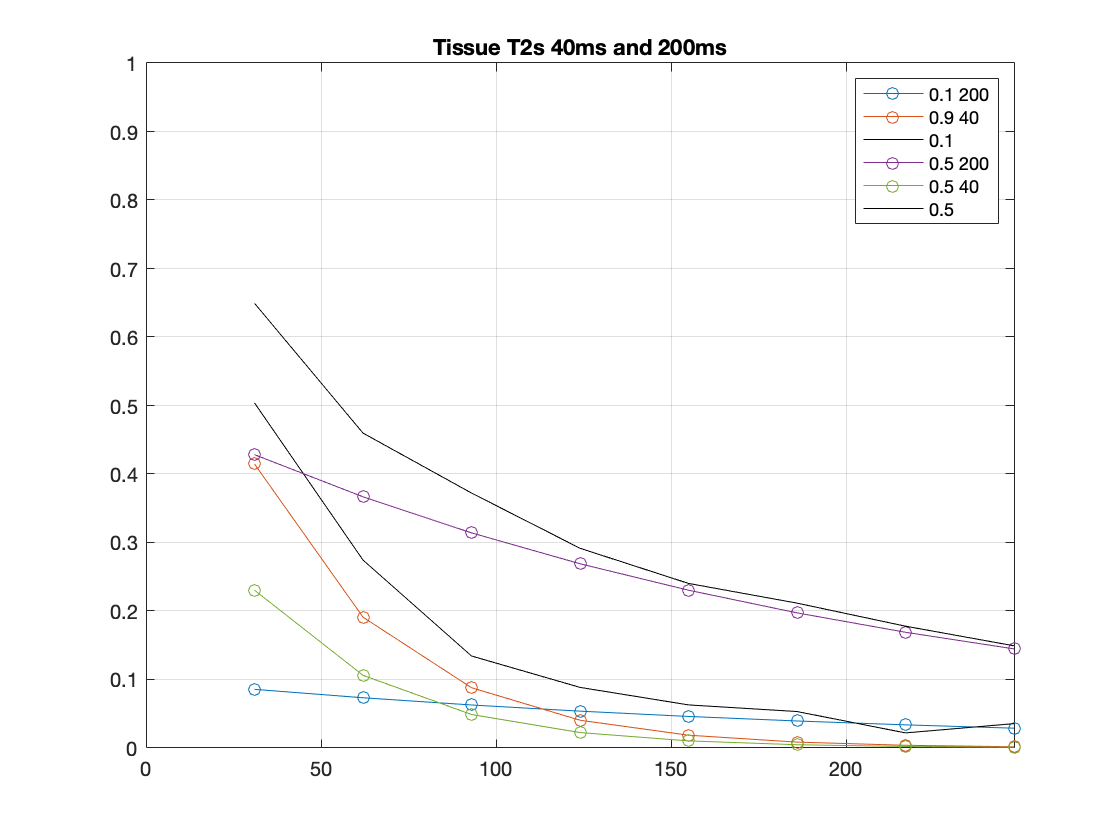

tiss(1).T1 = 1400 ; tiss(1).T2 = 200 ;  
tiss(2).T1 = 1400 ; tiss(2).T2 = 40  ;

tiss(3).T1 = 1400 ; tiss(3).T2 = 160 ;  
tiss(4).T1 = 1400 ; tiss(4).T2 = 60  ;

deltaTE = 31 ; 
necho = 8 ;
snr = 100 ;

figure
[S, Stot] = lws(tiss(1:2), [0.1 0.9], deltaTE, necho, snr ) ;
[S, Stot] = lws(tiss(1:2), [0.5 0.5], deltaTE, necho, snr ) ;
legend
title('Tissue T2s 40ms and 200ms')

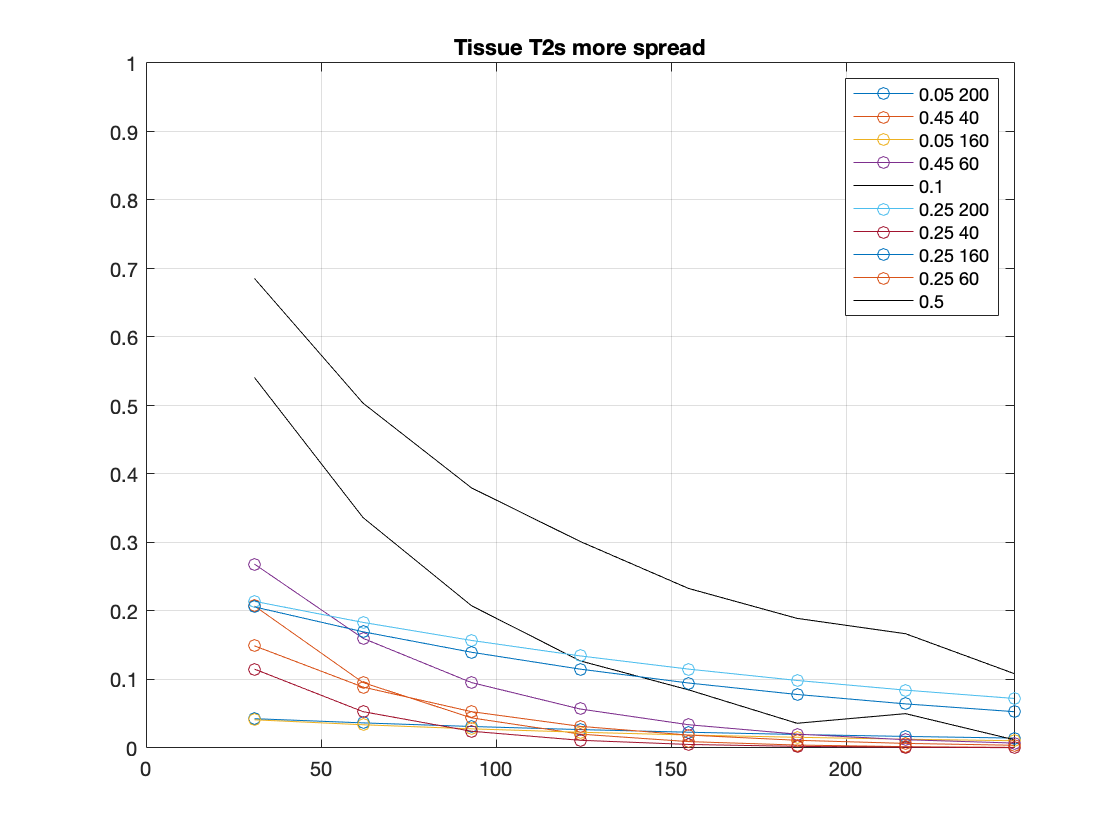


figure
[S, Stot] = lws(tiss(1:4), [0.05 0.45 0.05 0.45], deltaTE, necho, snr ) ;
[S, Stot] = lws(tiss(1:4), [0.25 0.25 0.25 0.25], deltaTE, necho, snr ) ;
legend
title('Tissue T2s more spread')

**Echo Phase Graph Approach**

EPG_T2(necho,te,t1,t2,A) from Will

Simultions show that for a constant flip angle train of 140 degrees, delteTE of 14, then between the 1st and 2nd echo the signal will drop for T2 of 40 or 60ms, but for 200 or 400ms, it will rise.  Suggests a possible short echo train with lower SAR.

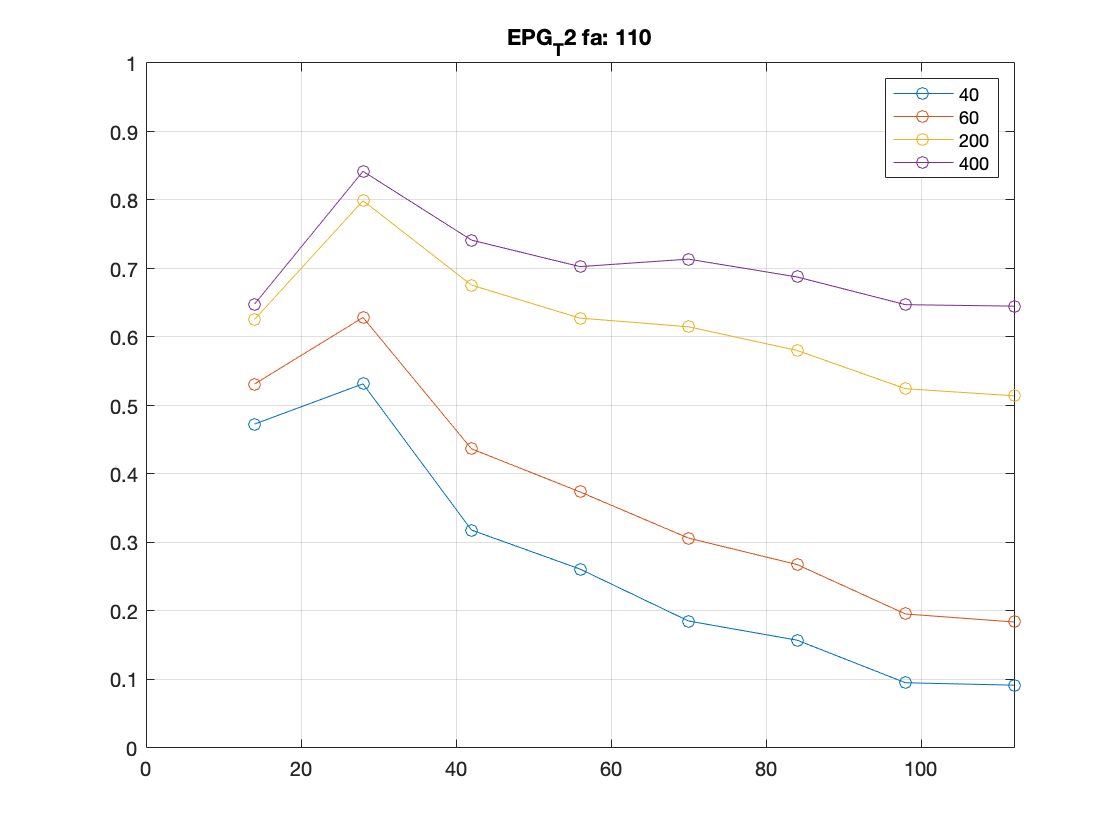

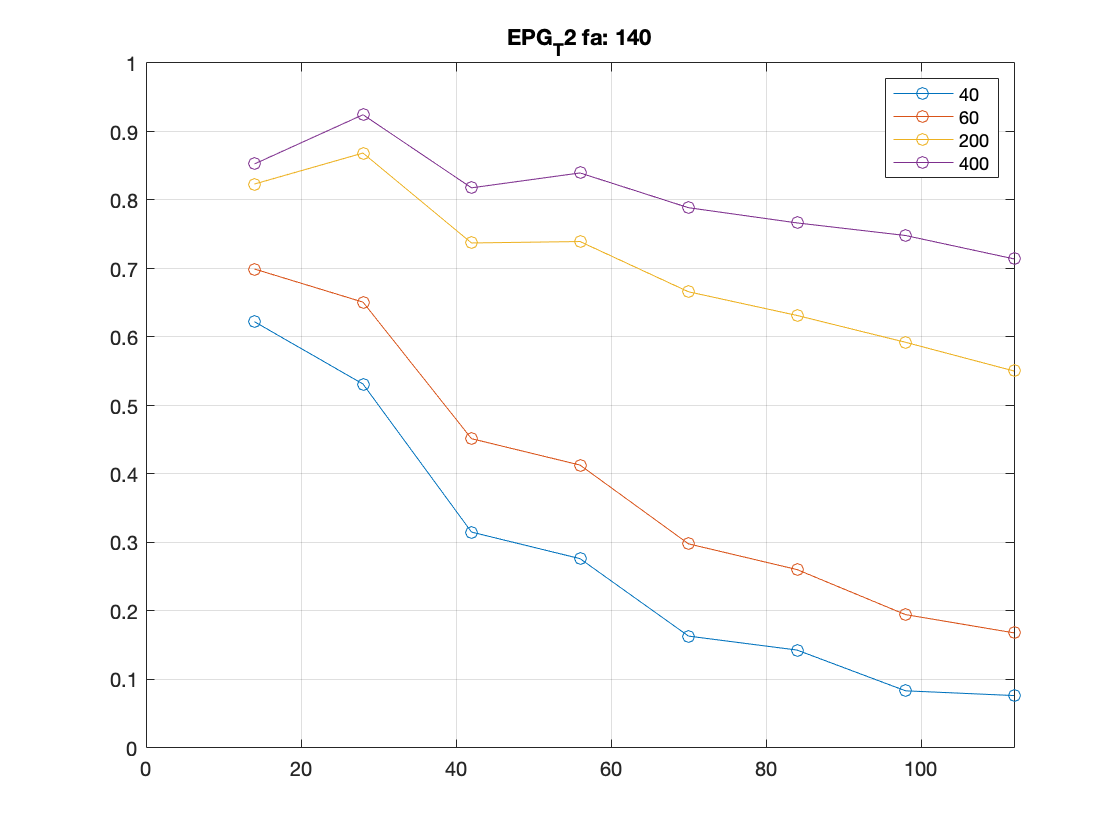

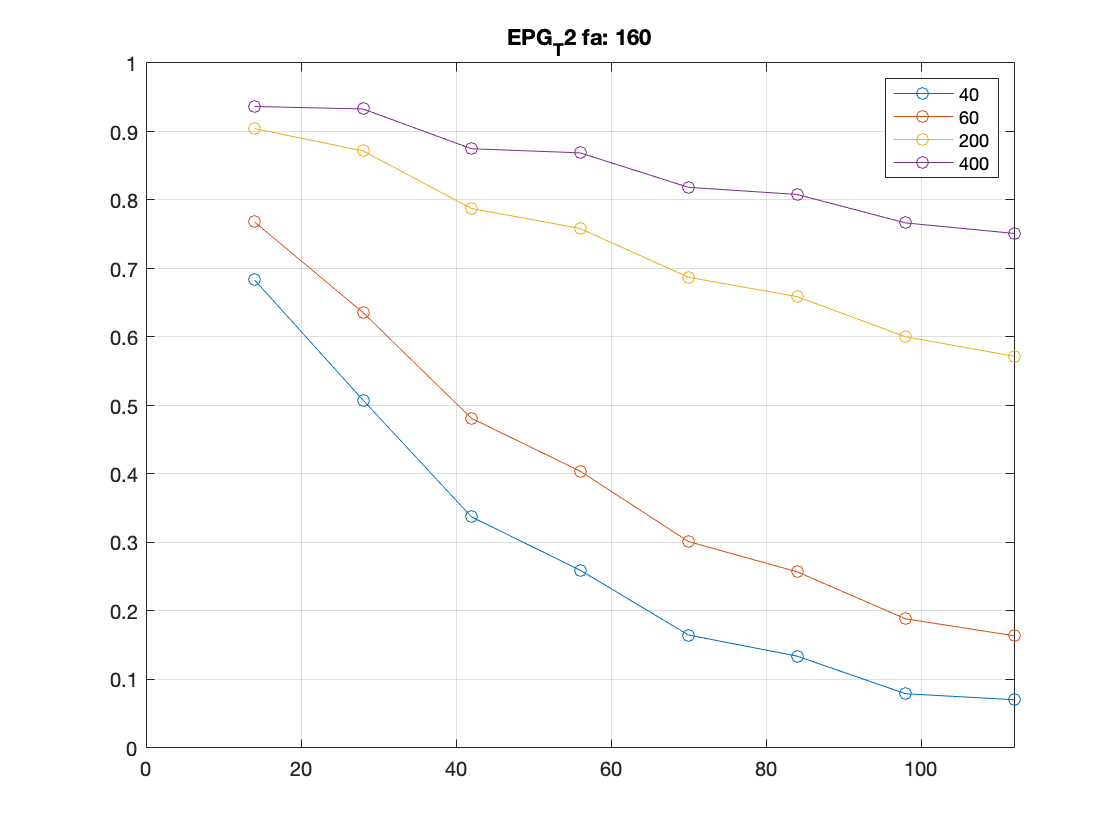

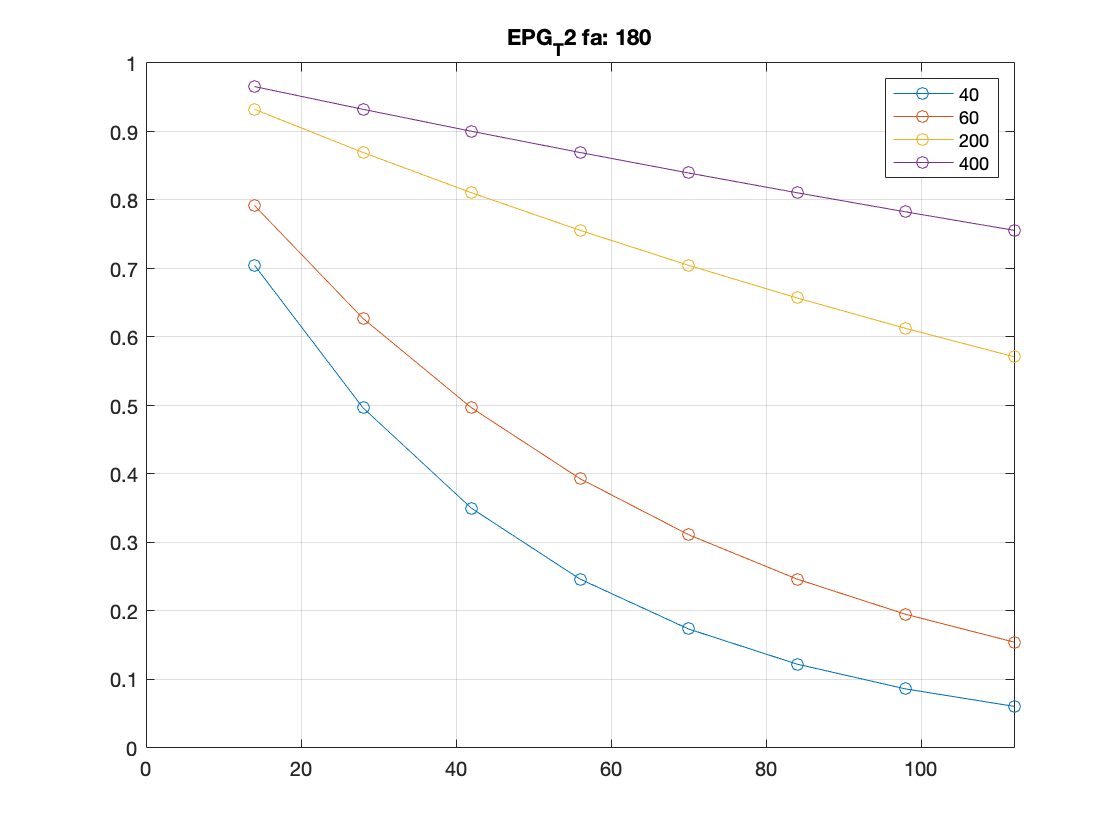

deltaTE = 14 ;
TEs = [1:necho]*deltaTE ;

fa = [110 140 160 180] ;
nfa = length(fa) ;
T2 = [40 60 200 400] ;
nT2 = length(T2) ;

T1 = 1400 ;

for ifa = 1:nfa
    figure
    A = repmat(fa(ifa)/360*2*pi, [1 necho]) ;
    for it2 = 1:nT2
        sig = EPG_T2(necho, TEs(1), T1, T2(it2), A);
        plot(TEs, sig, '-o','DisplayName',[num2str(T2(it2))]), hold on
    end
    axis([0 max(TEs) 0 1]), grid on, title(['EPG_T2 fa: ', num2str(fa(ifa))])
    legend
end

Repeat using Shaihan's code, first for one TR, then for multiple with shorter TR (as might be case if number of echoes reduced, then add some diffusion.

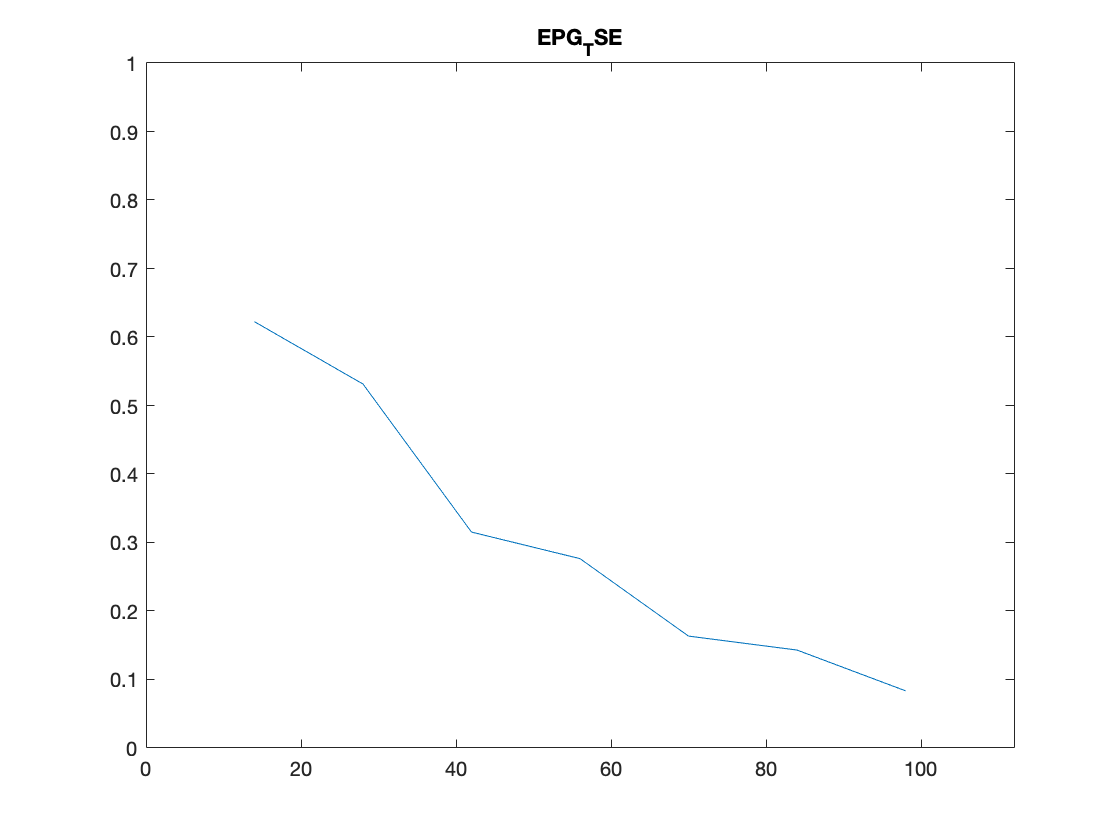

theta = [90 140 140 140 140 140 140 140]/360*2*pi ;
nrefoc = length(theta)-1;
[F0,Fn,Zn,F] = EPG_TSE(theta,deltaTE,T1,40) ;
figure
ts = [1:nrefoc] * deltaTE ;
plot(ts, abs(F0))
title('EPG_TSE')
axis([0 max(TEs) 0 1])

Function lws

function [S, Stot] = lws(tiss, vf, deltaTE, necho, snr)

if sum(vf(:)) ~= 1
    warning('Volume fractions do not total 1')
end

loc = find([tiss.T2]> 150) ;
lwf = sum(vf(loc))/(sum(vf(:))) ;

S0 = 1 ;

%  90   180    |     180      |
TEs = [1:necho]*deltaTE ;

Stot = zeros([1 necho]) ;

for ic = 1:length(tiss)
    S = S0 * exp(-TEs/tiss(ic).T2) ;
    Stot = Stot + S*vf(ic) ;
    plot(TEs,S*vf(ic),'-o','DisplayName',[num2str(vf(ic)),' ',num2str(tiss(ic).T2)]), hold on, grid on
end
% add image noise
Stot = abs(addimnoise(Stot,snr,1)) ;
plot(TEs,Stot,'k','DisplayName',num2str(lwf) )
axis([0 max(TEs) 0 S0])

end
